# **侧馈微带贴片天线**

**        微带贴片天线一般由两个不同大小的金属板、介质基板和辐射体等部分组成。本课程设计涵盖微带天线的原理介绍、设计方法、全波仿真及加工测试方法等。设计之前要先确定介质基板，计算微带贴片尺寸和馈电点的位置等，偏重全波仿真。该课程设计可以培养学生的机械制图能力、PCB 板加工能力、电磁仿真方法和天线测量能力等，并为今后就业、领域内深造打下基础。本小节将通过代码调用MATLAB中的天线工具箱实现微带贴片天线的设计。**

## **一、微带贴片天线的参数计算**

**        按要求输入设计指标**

clear;clc
c = 3e8;

**        介质材料的介电常数**

er=4;

**        介质材料的厚度小于Hmax时，可忽略表面波的损耗**


$$H_{max} =\frac{\lambda_0 }{2\pi \sqrt{\varepsilon_r }}$$


f = 2.45e9;
k = 2*pi*f/c;
Hmax = c/(2*pi*f*sqrt(er));
h=0.00179;

**        利用等效传输线模型法，可计算基模时辐射贴片的宽度**


$$w=\frac{c}{2f}(\frac{\varepsilon_r +1}{2})^{-\frac{1}{2}}$$


w = c/((2*f)*sqrt((er+1)/2));
fprintf('贴片的宽度w=%dm\n',w);

贴片的宽度w=3.872177e-02m


**        有效介电常数**


$$\varepsilon_e =\frac{\varepsilon_r +1}{2}+\frac{\varepsilon_r -1}{2}(1+12\frac{h}{w})^{-\frac{1}{2}}$$


ee=(er+1)/2+(er-1)/(2*sqrt(1+12*h/w));
fprintf('有效介电常数ee=%dm\n',ee);

有效介电常数ee=3.702996e+00m


**        等效辐射缝隙长度**


$$\Delta L=0\ldotp 412h\frac{(\varepsilon_e +0\ldotp 3)(w/h+0\ldotp 264)}{(\varepsilon_e -0\ldotp 258)(w/h+0\ldotp 8)}$$


detl = 0.412*h*(ee+0.3)*(w/h+0.262)/(ee-0.258)/(w/h+0.813);

**        微带波长**


$$\lambda_e =\frac{c}{f\sqrt{\varepsilon_e }}$$


lambdae = c/(f*sqrt(ee));
fprintf('介质基片内的波长为lambdae=%dm\n',lambdae);

介质基片内的波长为lambdae=6.363243e-02m


**        考虑到边缘缩短效应后，实际上的辐射单元长度应为 **


$$L=\frac{c}{2f\sqrt{\varepsilon_e }}-2\Delta L$$


l = lambdae/2-2*detl;
fprintf('辐射贴片的长度l0=%dm\n',l);

辐射贴片的长度l0=3.014443e-02m


wG = w+0.2*lambdae;
fprintf('介质基片的宽度wG=%dm\n',wG);

介质基片的宽度wG=5.144825e-02m


lG = l+0.2*lambdae;
fprintf('介质基片的长度lG=%dm\n',lG);

介质基片的长度lG=4.287091e-02m


## **二、天线工具箱仿真**

p1 = patchMicrostripInsetfed;

**        根据输入及计算结果，定义贴片天线最上层的金属贴片大小：**

p1.Length = l;
p1.Width = w;
p1.Height = h;
p1.NotchLength = 0;
p1.FeedOffset = [-lG/2 0];
p1.StripLineWidth = 1e-3;

**        定义最下层的金属接地板大小：**

p1.GroundPlaneLength = lG;
p1.GroundPlaneWidth = wG;

**        设置一个材料库中没有的新材料，介电常数为er：**

p1.Substrate = dielectric('Name','material1','EpsilonR',er);

**        也可以在材料库中选择一种材料**

% openDielectricCatalog %调出介质基板的材料库
% p1.Substrate = dielectric('FR4'); %选择FR4

**        显示设计出的PCB图：**

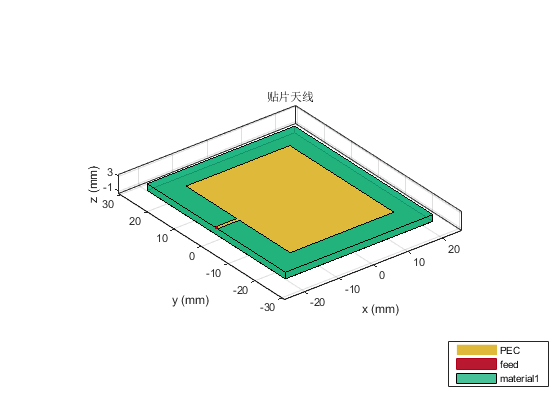

pb1 = pcbStack(p1);
figure
show(pb1);
title('贴片天线');
set(gcf,'Visible','on');   	    %强制图片弹出显示
hold off 

**        对仿真区域进行网格划分：**

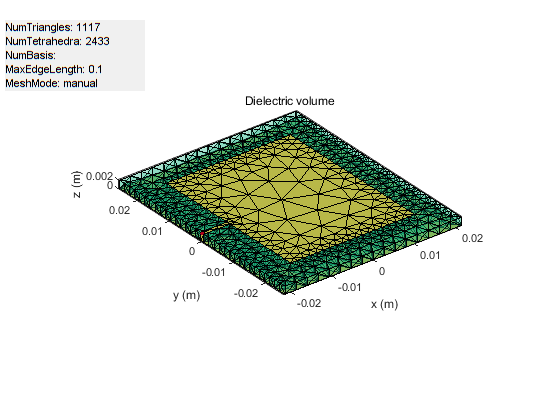

figure
mesh(pb1,'MaxEdgeLength',.1,'MinEdgeLength',.003);

**        绘制阻抗分布图：**

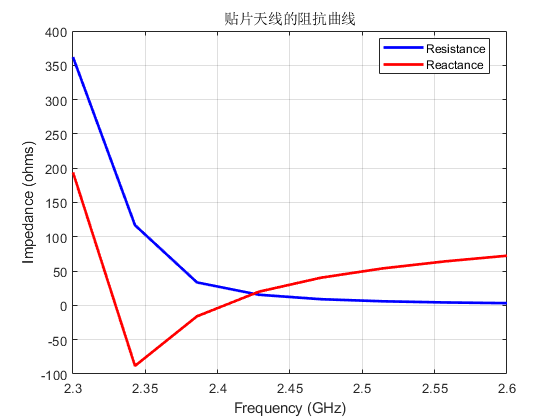

figure
impedance(pb1,linspace(2.3e9,2.6e9,8));
title('贴片天线的阻抗曲线');

**        S参数：**

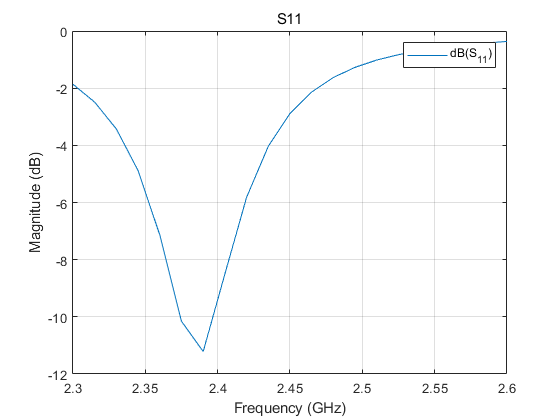

S=sparameters(pb1,linspace(2.3e9,2.6e9,21));
figure
rfplot(S);
title('S11');
set(gcf,'Visible','on');   	    %强制图片弹出显示

**        为了改善阻抗特性，还需要进行扫参优化。**

## **三、扫参优化**

**        改变贴片长度，将谐振点移至2.45GHz**

**        可视化变化趋势：**

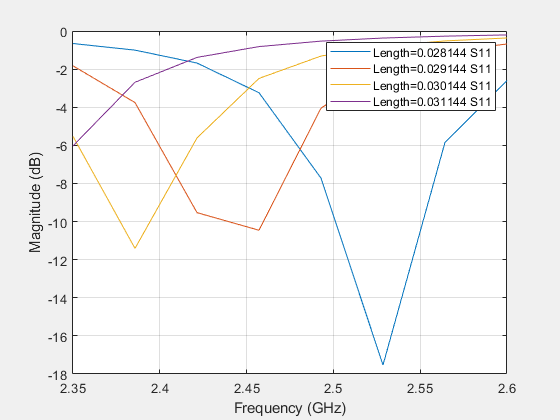

legE=[];
figure
set(gcf,'Visible','on');   	    %强制图片弹出显示
for Length = l-2e-3:1e-3:l+1e-3
    p1.Length = Length;
    pb1 = pcbStack(p1);
    m = mesh(pb1,'MaxEdgeLength',.1,'MinEdgeLength',.003);
    S = sparameters(pb1,linspace(2.35e9,2.6e9,8));
    rfplot(S);
    legE = [legE , strcat('Length=', string(Length), ' S11')];
    hold on
end
legend(legE);

**        从参数扫描结果中可以看出，改变贴片长度可以优化天线的谐振频率。**

**        仿真不同贴片长度单个频点（2.45GHz）的S参数，寻找最优值，并修改贴片长度：**

S11_value=0;
for Length = l-2e-3:0.1e-3:l+2e-3
    p1.Length = Length;
    pb1 = pcbStack(p1);
    m = mesh(pb1,'MaxEdgeLength',.1,'MinEdgeLength',.003);
    S = sparameters(pb1, f);
    S11_value_op = 20 * log10(abs(S.Parameters(1, 1)));
    if S11_value > S11_value_op
        S11_value = S11_value_op;
        BestLength=Length;
    end
end
p1.Length = BestLength;
fprintf('最佳贴片长度BestLength=%dm\n',BestLength);

最佳贴片长度BestLength=2.904443e-02m


**        改变微带线宽度，实现更好的阻抗匹配：**

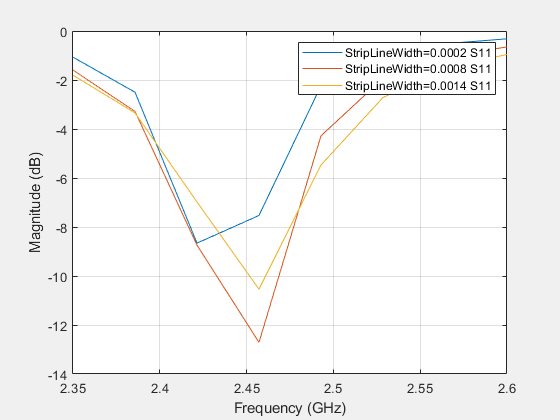

legE=[];
figure
set(gcf,'Visible','on');   	    %强制图片弹出显示
for StripLineWidth = 0.2e-3:0.6e-3:1.4e-3
    p1.StripLineWidth = StripLineWidth;
    pb1 = pcbStack(p1);
    m=mesh(pb1,'MaxEdgeLength',.1,'MinEdgeLength',.003);
    S = sparameters(pb1,linspace(2.35e9,2.6e9,8));
    rfplot(S);
    legE = [legE , strcat('StripLineWidth=', string(StripLineWidth), ' S11')];
    hold on
end
legend(legE);

**        从参数扫描结果中可以看出，改变微带线宽度几乎不会改变天线的谐振频率。**

**        仿真不同微带线宽度在单个频点（2.45GHz）的S参数，寻找最优值，并修改微带线宽度：**

S11_value=0;
for StripLineWidth = 0.2e-3:0.2e-3:1.4e-3
    p1.StripLineWidth = StripLineWidth;
    pb1 = pcbStack(p1);
    m=mesh(pb1,'MaxEdgeLength',.1,'MinEdgeLength',.003);
    S = sparameters(pb1, f); 
    S11_value_op = 20 * log10(abs(S.Parameters(1, 1)));
    if S11_value > S11_value_op
        S11_value = S11_value_op;
        BestStripLineWidth=StripLineWidth;
    end
end
p1.StripLineWidth = BestStripLineWidth;
fprintf('最佳微带线宽度BestStripLineWidth=%dm\n',BestStripLineWidth);

最佳微带线宽度BestStripLineWidth=4.000000e-04m


## **四、结果仿真**

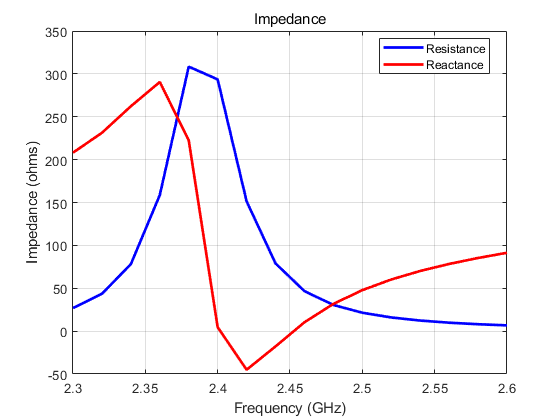

pb1 = pcbStack(p1);
m=mesh(pb1,'MaxEdgeLength',.1,'MinEdgeLength',.003);
figure
impedance(pb1,linspace(2.3e9,2.6e9,16))
set(gcf,'Visible','on');   	    %强制图片弹出显示

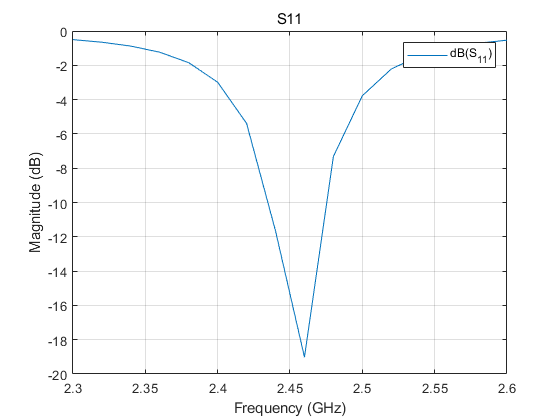

figure
S=sparameters(pb1,linspace(2.3e9,2.6e9,16));
rfplot(S);
title('S11');
set(gcf,'Visible','on');   	    %强制图片弹出显示

**        绘制在2.45 GHz处的天线方向图：**

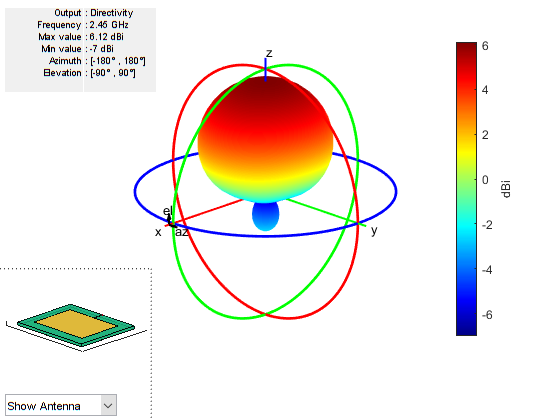

figure
pattern(pb1, f);

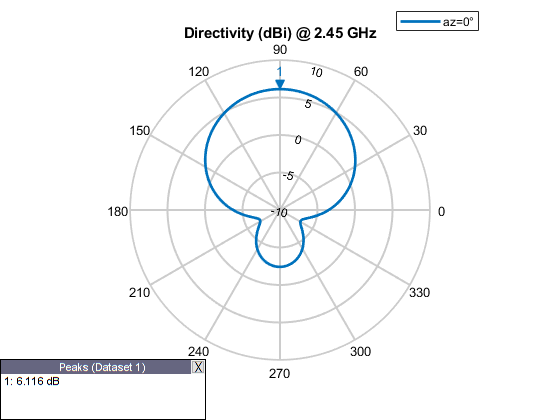

figure
patternElevation(pb1, f);

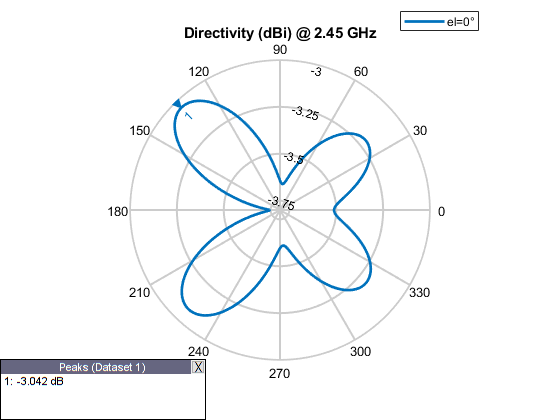

figure
patternAzimuth(pb1, f);

## **参考文献：**

**        [1] **[**https://www.mathworks.com/help/antenna/ref/patchmicrostripinsetfed.html**](https://www.mathworks.com/help/antenna/ref/patchmicrostripinsetfed.html)

**        [2] 李明洋. HFSS天线设计[M].北京: 电子工业出版社,2011.**

**        [3] 刘学观, 郭辉萍. 微波技术与天线[M]. 西安: 西安电子科技大学出版社,2015.**